## Image Recognition

This example walks through a basic image recognition task. The data is 4 categories of objects, which can be classified using GoogleNet and transfer learning. 

## Step #1: Load the Data

Unzip this small dataset and use imageDatastore to manage the data. 

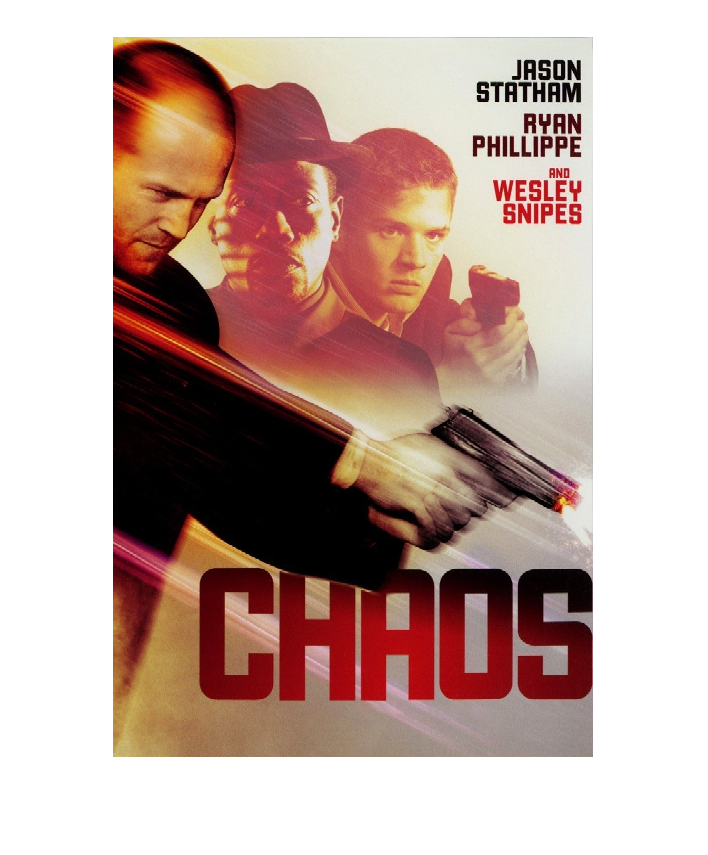

unzip('C:\Users\Shreyas Desai\Desktop\test\Action movies.zip');
imds = imageDatastore('C:\Users\Shreyas Desai\Desktop\test\Action movies', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);

% visualize a random image
I = readimage(imdsTrain,randi(numel(imdsTrain.Files)));
imshow(I);

## Step #2: Import Network and Resize data

The network imported and the image data must be the same size to work. The easiest way is to resize the data. We can then use the network to see how it classifies the data, before retraining

net = googlenet;

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

% pull a test sample
test_sample_table = augimdsTrain.readByIndex(1);
test_sample = test_sample_table.input{1};

% use GoogLeNet to classify image
label = classify(net,test_sample)

label = categorical
     comic book 


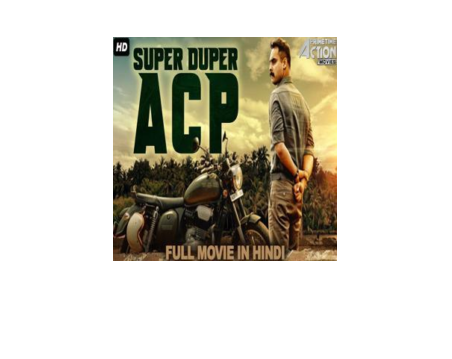

imshow(test_sample);

## Step #3: Transfer Learning

Transfer learning involves modifying an existing network to work for new data. The final layers need to be replaced in order to work with this dataset. For larger datasets, training a network can take a long time. This should train relatively quickly in a few minutes. 

lgraph = layerGraph(net);

numClasses = numel(categories(imdsTrain.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);

lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Plots','training-progress');

newNet = trainNetwork(augimdsTrain,lgraph,options);

Error using trainNetwork (line 183)
Unable to read file: 'C:\Users\Shreyas Desai\Desktop\test\Action movies\01 (5).jpg'.

Caused by:
    Error using matlab.io.datastore.ImageDatastore/read (line 77)
    Unable to read file: 'C:\Users\Shreyas Desai\Desktop\test\Action movies\01 (5).jpg'.
        Error usi

## Step #4: Classify on new data

Testing all images in the validation set can give a quick assessment of how well the network trained. You can also visualize the results with their predictions on individual images. 

[YPred,probs] = classify(newNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

% And view individual images

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end
